# Hand Posture Recognition- K-means clustering, find optimum number of clusters using silhouette criterion

## Load data

data_path = 'hand_posture.csv';
%dataset from https://archive.ics.uci.edu/ml/datasets/MoCap+Hand+Postures
hand_pos_data = readtable(data_path, 'TreatAsEmpty',{'?', ' ', '.','NA'});  
%clean the data; Replace the mentioned elements with NaN
%readtable handle all data types present in the table and retains the
%header too, hence it is better than readcsv and readxls

data = hand_pos_data(1:end, 3:20); 
labels = hand_pos_data(1:end, 1);
disp(['Data ', num2str(size(data))])

Data 78095     18


disp(['Dataset consists of ',num2str(size(data,1)), ' samples and ',num2str(size(data,2)),' features '])

Dataset consists of 78095 samples and 18 features 


classes = unique(table2array(labels));
disp(['Classes in dataset: ',num2str(classes')]);

Classes in dataset: 1  2  3  4  5


feature_names = [];  %create a string array containing feature names
for i=1:width(data)
    x = data.Properties.VariableNames(i);
    feature_names = [feature_names, string(x{1})];
end
disp(['Features in data: ', feature_names])

  Columns 1 through 14

    "Features in data: "    "X0"    "Y0"    "Z0"    "X1"    "Y1"    "Z1"    "X2"    "Y2"    "Z2"    "X3"    "Y3"    "Z3"    "X4"

  Columns 15 through 19

    "Y4"    "Z4"    "X5"    "Y5"    "Z5"



## Data cleaning

dataset_array = table2dataset(data); %dataset arrays are arrays for statistical data

messy_data = dataset_array;
%Find samples with missing values
ix = ismissing(messy_data, 'StringTreatAsMissing', {'?',' ','NaN','.','NA'});
[rowIdcs, ~]  = find(sum(ix,2)~=0);
disp([num2str(length(rowIdcs)), ' obervations in total have missing values']); 

13023 obervations in total have missing values


disp(['These samples will be removed']);

These samples will be removed


%Create a dataset array with complete observations
%Create the new clean dataset that is = old data minus all missing
%obervations

ix = ismissing(messy_data);
cleaned_data = messy_data(~any(ix,2),:);
disp(['New cleaned data: ', num2str(size(cleaned_data))]);

New cleaned data: 65072     18


## Normalize data

X_norm = mapstd(double(cleaned_data)')';  %later, we do PCA that needs data normalized along columns
disp(['Normalize data so it has zero mean and unity standard deviation']);

Normalize data so it has zero mean and unity standard deviation


disp(['Data mean = ', num2str(mean(X_norm(:))), ', standard deviation = ', num2str(std(X_norm(:)))]);

Data mean = -2.3697e-16, standard deviation = 0.99999


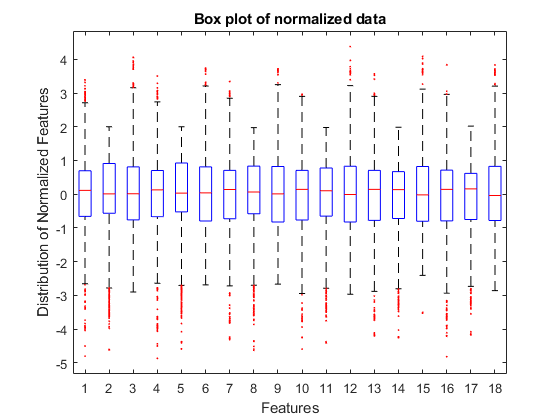

%% View and remove outliers
boxplot(X_norm, 'OutlierSize',1, 'Symbol', 'ro');
title('Box plot of normalized data');
xlabel('Features');
ylabel('Distribution of Normalized Features');

TF = isoutlier(X_norm, 'quartile');
%method is quartile => we eliminate outliers that lie above or below 1.5* IQR(interquartile range = 50 percentitle = Q3-Q1)_
sum_TF = sum(TF,2);  
%sum TF row wise to find samples with outliers; array containing 1 corresponding to samples with outliers
nt_outlier_idx = find(sum_TF == 0);
outlier_idx = find(sum_TF ~= 0);
disp(['Data consists of ', num2str(length(outlier_idx)), ' outliers.']);

Data consists of 611 outliers.


X_outliers_rmvd = X_norm(nt_outlier_idx, :);
disp(['Data after outlier removal: ', num2str(size(X_outliers_rmvd))]);

Data after outlier removal: 64461     18


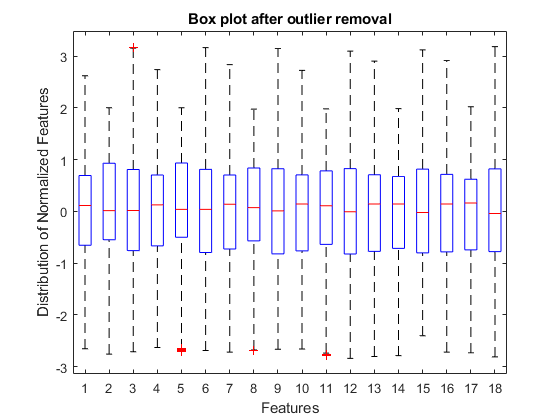

boxplot(X_outliers_rmvd);
title('Box plot after outlier removal');
xlabel('Features');
ylabel('Distribution of Normalized Features');

## Elbow plot to find optimum number of principal components

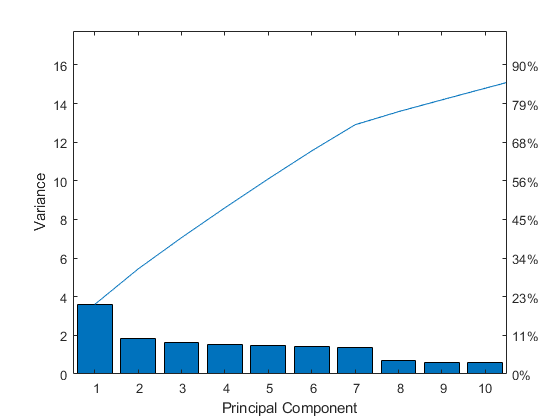

[loadings, X_pca_, variances, tscores] = pca(X_outliers_rmvd);
figure;
pareto(variances);
xlabel('Principal Component')
ylabel('Variance')

n_comp = 2;
X_pca = X_pca_(:, 1:n_comp);
disp(['Data after PCA: ', num2str(size(X_pca))]);

Data after PCA: 64461      2


## Run parallel pool

p = gcp('nocreate');
if isempty(p)
    p = parpool('local');
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.


## K-means Clustering- find the optimal number of clusters using silhouette criterion

cluster_options = statset('UseParallel',1);
kmeans_algo = @(X,K)(kmeans(X, K, 'emptyaction','singleton','distance', 'cosine',...
    'replicates', 6,'options',cluster_options));

max_clusters = 6;
cluster_evaluation = evalclusters(X_pca, kmeans_algo, 'silhouette', 'KList', (1:max_clusters));

> In kmeans/loopBody (line 468)
  In parallel_function>make_general_channel/channel_general (line 926)
  In remoteParallelFunction (line 41)
> In kmeans/loopBody (line 468)
  In parallel_function>make_general_channel/channel_general (line 926)
  In remoteParallelFunction (line 41)


disp(['Result of cluster evaluation'])

Result of cluster evaluation


disp(cluster_evaluation);

  SilhouetteEvaluation with properties:

    NumObservations: 64461
         InspectedK: [1 2 3 4 5 6]
    CriterionValues: [NaN 0.5854 0.5365 0.4934 0.4660 0.4245]
           OptimalK: 2



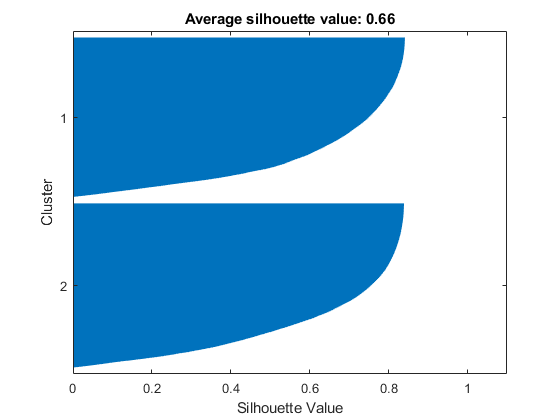

best_cluster_val = cluster_evaluation.OptimalK;

% Now perform K-Means Clustering with this optimum value of clusters
[cent_indices, cent_locations] = kmeans_algo(X_pca, best_cluster_val);
[sil_value,h] = silhouette(X_pca, cent_indices, 'cosine');
title(sprintf('Average silhouette value: %0.2f', mean(sil_value)))

ptsymb = {'r.', 'g.', 'b.', 'm.', 'c.'};
for i = 1:n_clusters
    cluster = find(cent_indices==i);
    plot(X_pca(cluster,1),X_pca(cluster,2),ptsymb{i});
    hold on
end

plot(cent_locations(:,1), cent_locations(:,2),'*k','LineWidth', 7);
title('Plot samples belonging to each cluster')
hold off
xlabel('Principal component 1');
ylabel('Principal component 2');
legend('cluster 1','cluster 2', 'cluster3', 'cluster 4', 'cluster 5', 'centroids')

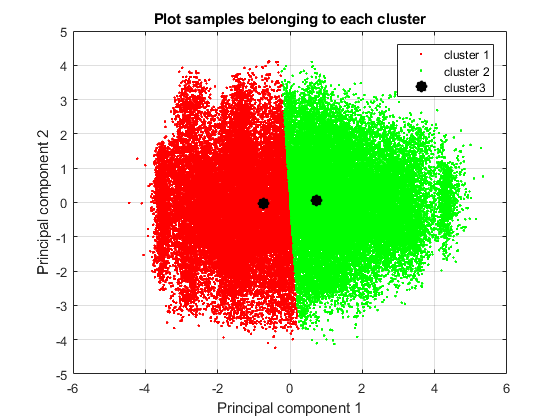

grid on